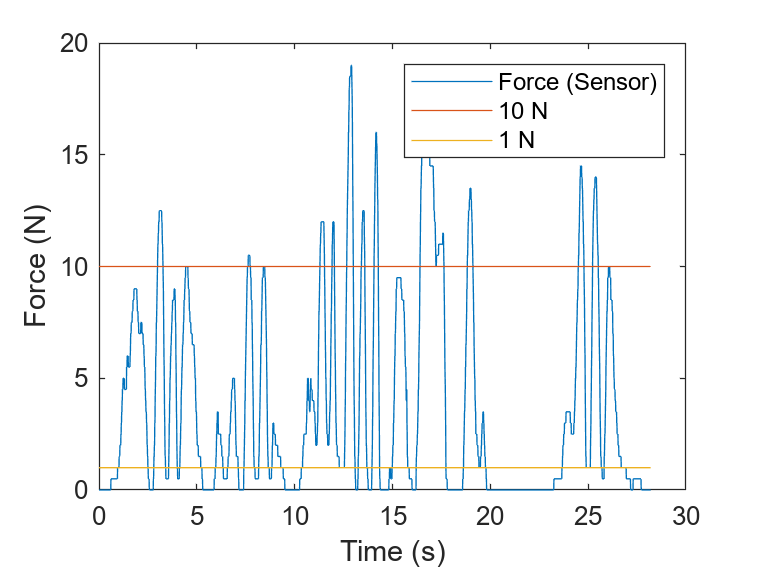

%EXTRACT THE DATA FROM THE FOLDER           
[file,path] = uigetfile('*.txt','Select the .txt file');
            
            filename = file;

            data = fileread(filename);
            data = strrep(data,',','.');
            fid = fopen(filename,'w');
            fwrite(fid,data,'char');
            fclose(fid);

            opt = {'CollectOutput',true};
            hdr = {};
            out = {};
            [fid,msg] = fopen(filename,'rt');
            assert(fid>=3,msg) % ensure the file opened correctly.
            fgetl(fid); % read and ignore the very first line.
            while ~feof(fid)
                hdr{end+1} = fgetl(fid);
                out(end+1) = textscan(fid,'%f%f',opt{:});
            end
            fclose(fid);

%AO -->  REPRESENTATION OF FORCES IN RELATION TO TIME ON A GRAPH 
            A0 = out{1,3};

            t1 = A0(:,1);

            A = @(t1) interp1(A0(:,1), A0(:,2), t1, 'linear');

            t = 0:0.01:(size(A0,1)-1)*0.01;

            plot(t,A(t))
            
            xlabel('Time (s)');
            
            ylabel('Force (N)');

            
            hold on

            % F_10 = 10*ones(size(t))
            F_10 = @(t1) 10*ones(size(t1));
            F_1 = 1*ones(size(t));
            plot(t, F_10(t));
            plot(t, F_1);
            legend('Force (Sensor)', '10 N', '1 N')
            
           
            hold off

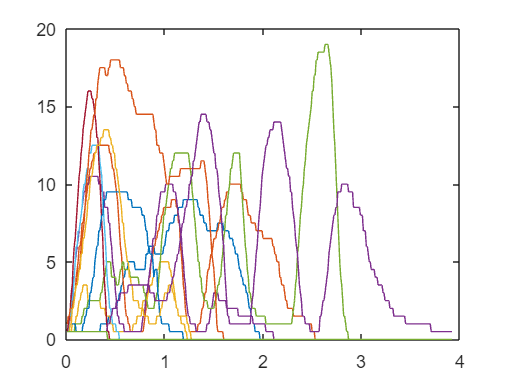

            
            
         
%WE STORE THE FORCE AND TIME DATA IN TWO DISTINCT VECTORS
            Time=A0(:,1);
            Force=A0(:,2);
            SizeForce=size(Force);
            SizeOfTime=size(Time);
            TotalTimeOfVideo=SizeOfTime(1,1)*0.01;

%DATA FOR LOOPS
            ForceData=0;
            TimeData=0;
            ForceVector=0;
            TimeVector=0;
            ForceCounterForRows=0;
            ForceCounterForColums=1;
        
%WE RUN THE FORCE VECTOR TO KNOW WHEN THE FORCE VALUE IS NOT F=0N
            ReferenceData=input('Indicate the reference data value to apply:');
            for i=1:SizeForce(1,1)
                %We save the value of the force
                ForceData=Force(i,1);
                TimeData=Time(i,1);
                if ForceData>ReferenceData
                    ForceCounterForRows=ForceCounterForRows+1;
                    ForceVector(ForceCounterForRows,ForceCounterForColums)=ForceData;
                    TimeVector(ForceCounterForRows,ForceCounterForColums)=TimeData;
                else
                    ForceCounterForRows=0;
                    ForceCounterForColums=ForceCounterForColums+1;
                   
                end
            end

 %WE ELIMINATE THE COLUMS OF 0
 SumOfVectors=sum(ForceVector);
 SizeOfSum=size(SumOfVectors);
 for c=SizeOfSum(1,2):-1:1
     Sum=SumOfVectors(1,c);
     if Sum==0
         ForceVector(:,c)=[]; 
         TimeVector(:,c)=[];
     end
 end


  %ANALISING OF EACH FORCE
SizeOfForce=size(ForceVector);
Percentile=input('Indicate the percentile value to apply:');
 for s=1:SizeOfForce(1,2)
     %WE SAVE EACH VECTOR OF FORCES IN AN INDEPENDENT VECTOR 
     x{1,s}=ForceVector(:,s);
     %WE SAVE EACH VECTOR OF TIME IN AN INDEPENDENT VECTOR 
     x{2,s}=TimeVector(:,s);
     CounterTime=0;
     for c=1:SizeOfForce(1,1)
         if x{1,s}(c,1)>0
             CounterTime=CounterTime+1;
         end
     end
     % WE SAVE THE DURATION TIME
     x{3,s}=CounterTime*0.01;
     % PERCENTILE FORCE OF THE VECTOR 
     x{4,s}=prctile(x{1,s},Percentile);
     %CATEGORIE --> C1=FORCES 0-1N/ C2=FORCES 1-10N / C3=FORCES 10-60N /
     %C4=PEAK FORCE
     if x{4,s}<1
        x{5,s}='c1';
     else if x{4,s}>=1 && x{4,s}<10
             x{5,s}='c2';            
     else if x{4,s}>=10 && x{4,s}<=60
             x{5,s}='c3';            
     end
     end
     end
     
     if x{3,s}<1
             x{5,s}='peakforce';       
     end
     
 end



 %DATA PLOT OF ALL FORCES
 SizeOfForce=size(ForceVector);
 TimeOfDuration=SizeOfForce(1,1)*0.01;
 for t=1:SizeOfForce(1,2)
     TimeForPlot = 0.01:0.01:TimeOfDuration;
     ForceForPlot=ForceVector(:,t);
     plot(TimeForPlot,ForceForPlot)
     hold on
 end

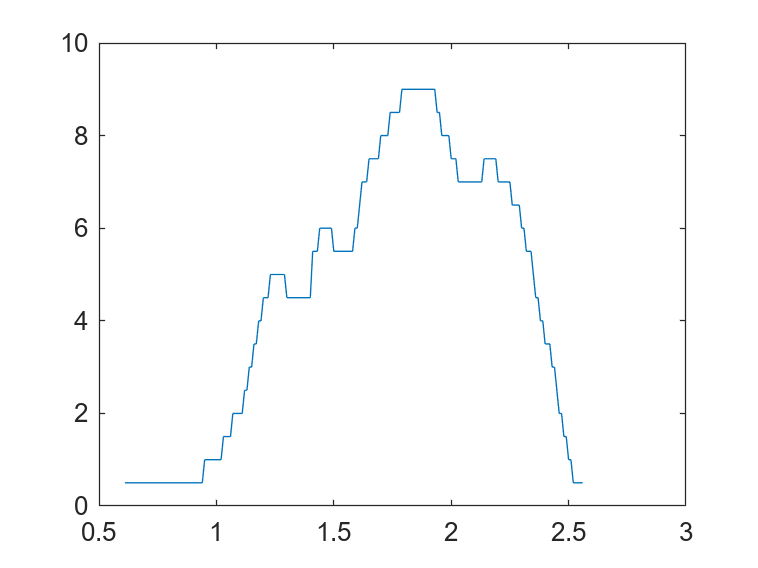

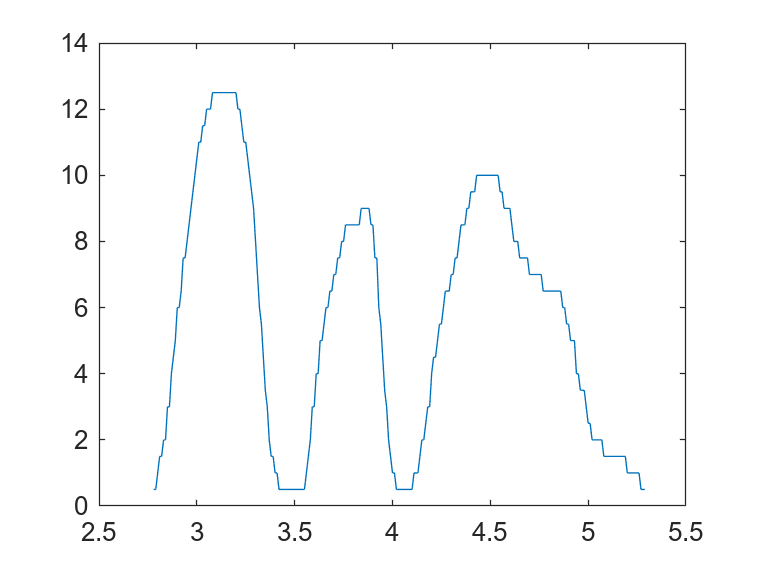

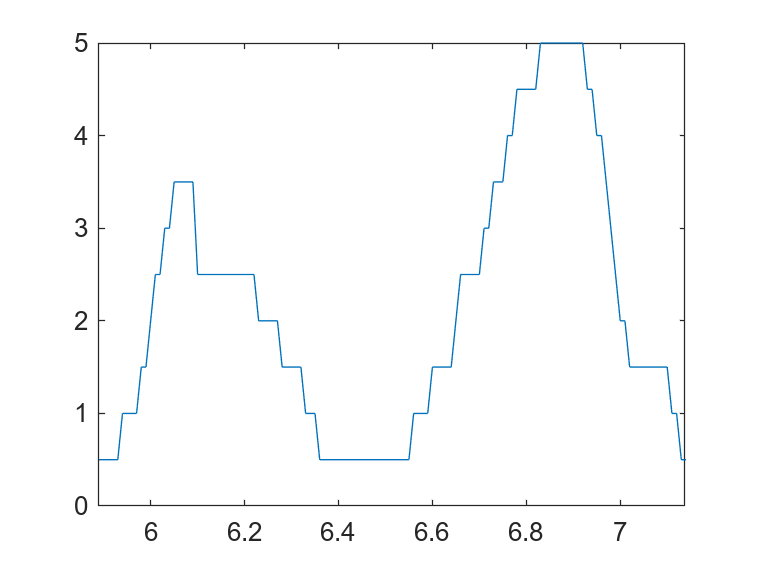

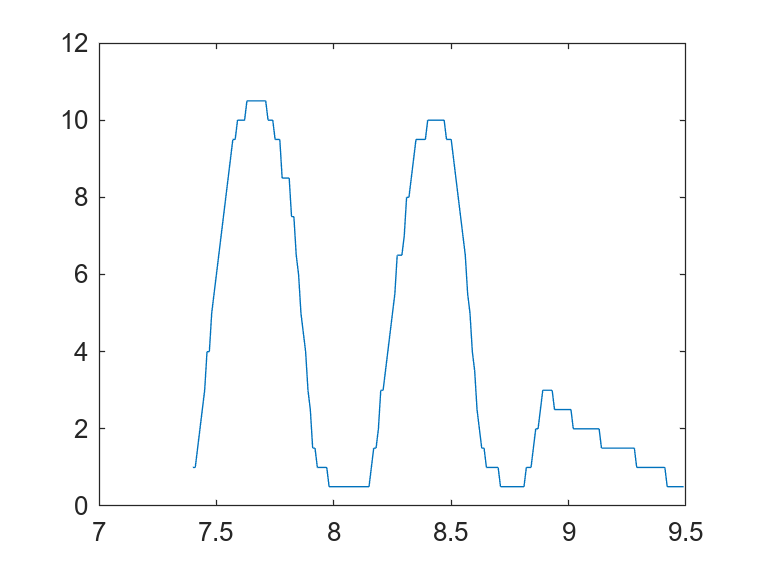

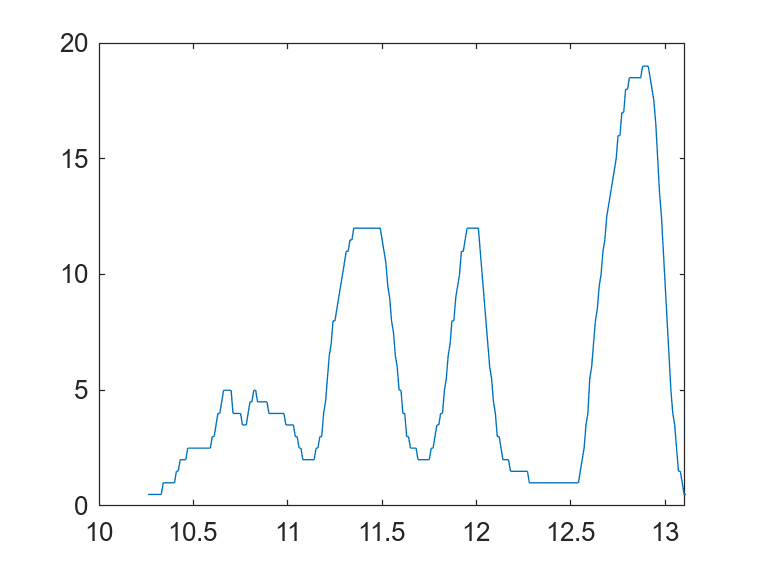

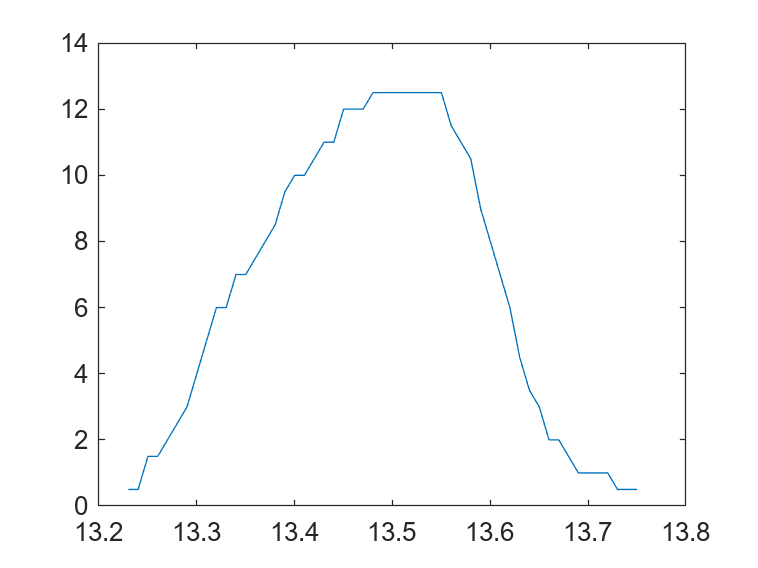

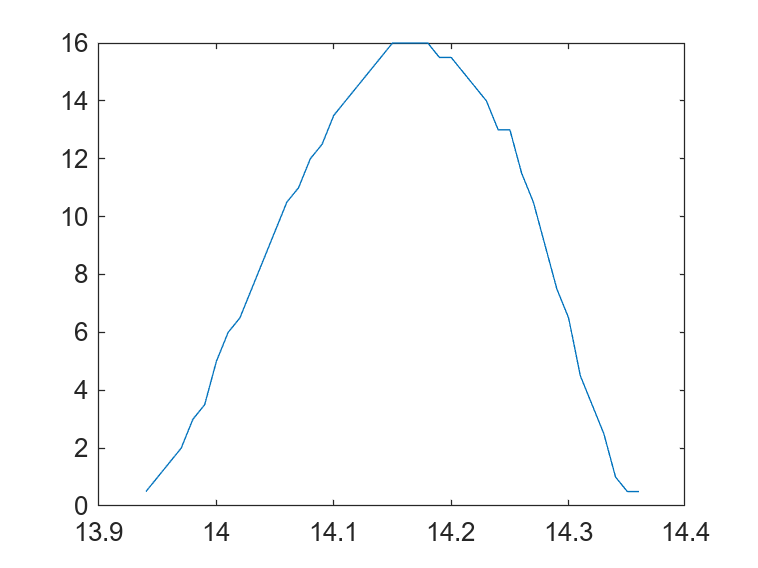

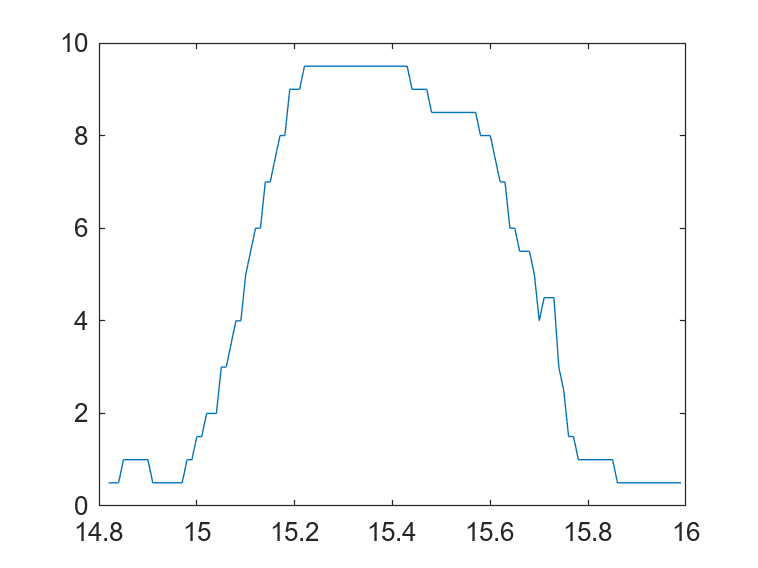


 %DATA PLOT OF SINGLE FORCES
 SizeOfForce=size(ForceVector);
 TimeOfDuration=SizeOfForce(1,1)*0.01;
 for t=1:SizeOfForce(1,2)
     TimeForPlot2=TimeVector(:,t);
     ForceForPlot=ForceVector(:,t);
     indiceTime=find(TimeForPlot2==0);
     indiceForce=find(ForceForPlot==0);
     TimeForPlot2(indiceTime)=[];
     ForceForPlot(indiceForce)=[];
     figure
     plot(TimeForPlot2,ForceForPlot)
     hold on
 end

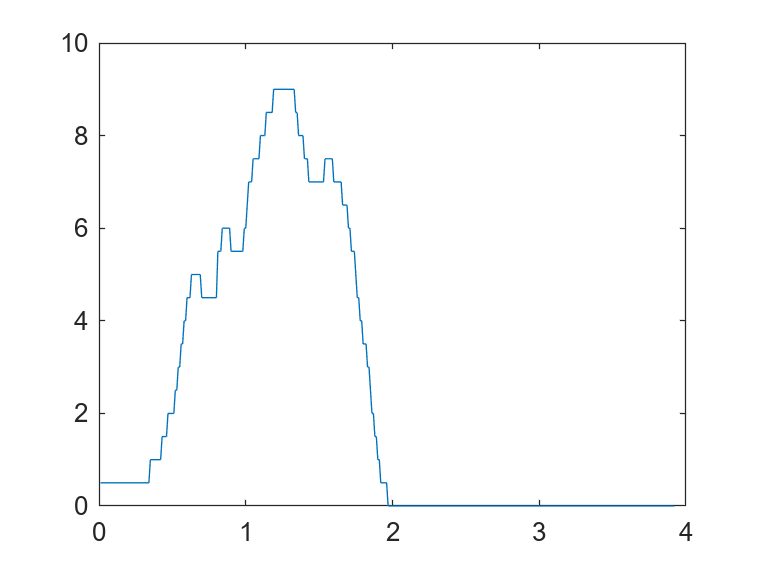

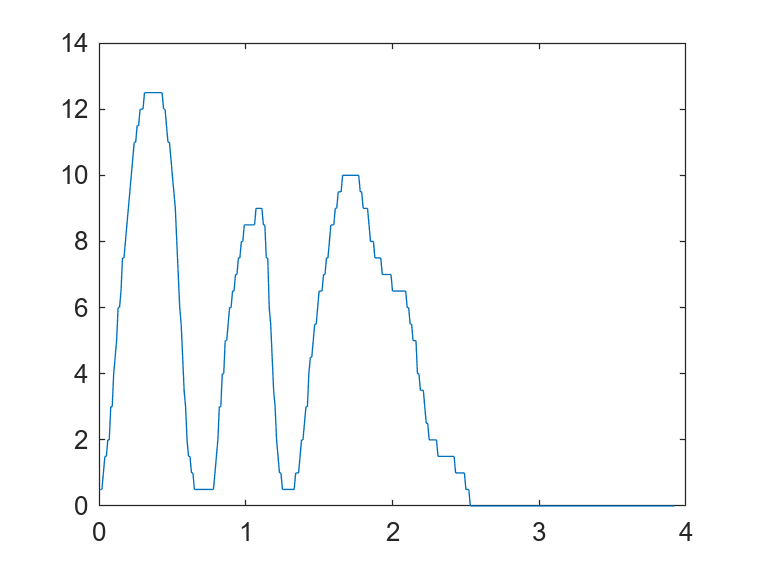

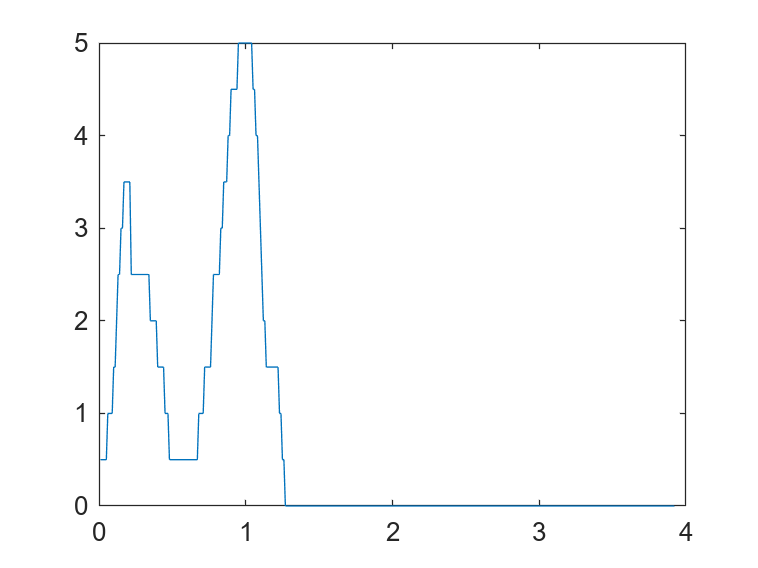

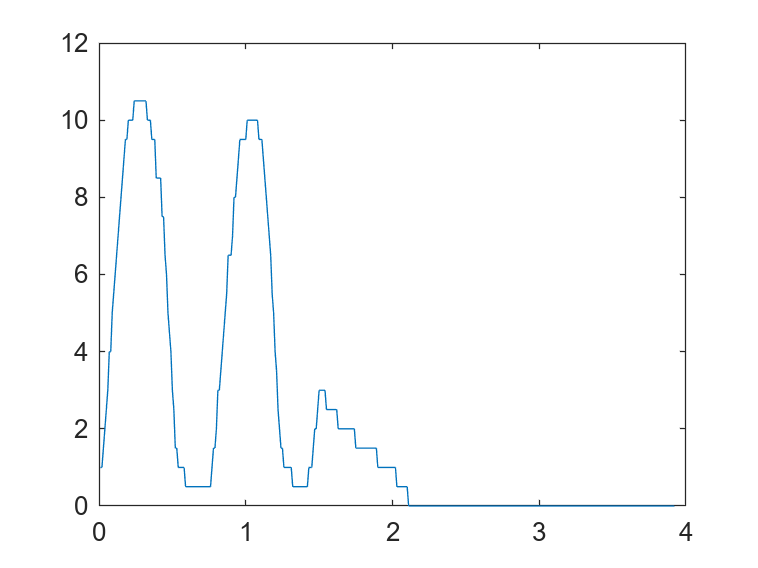

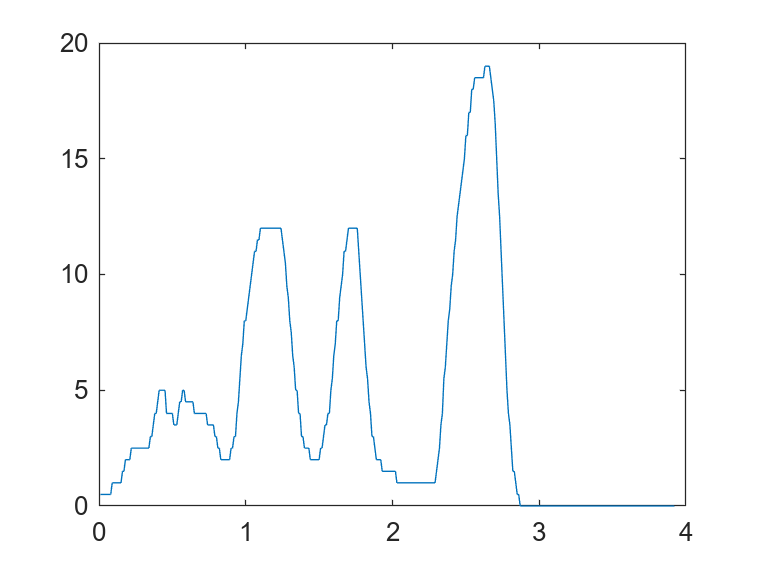

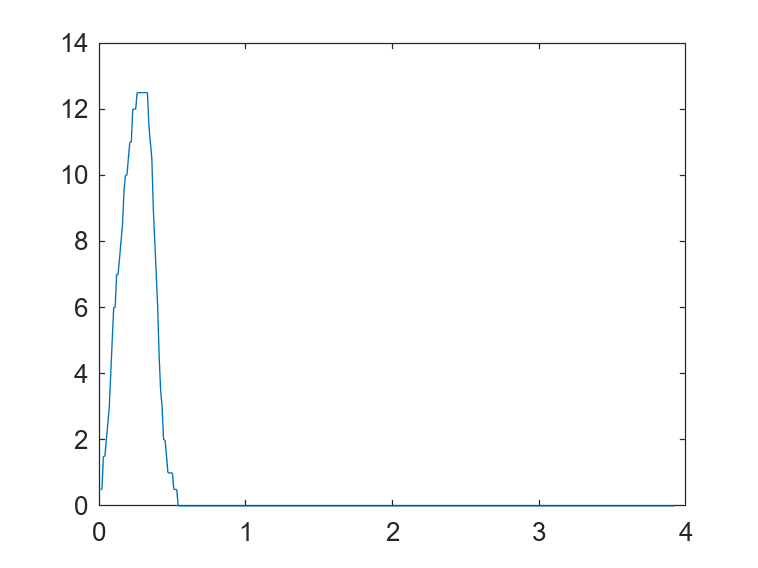

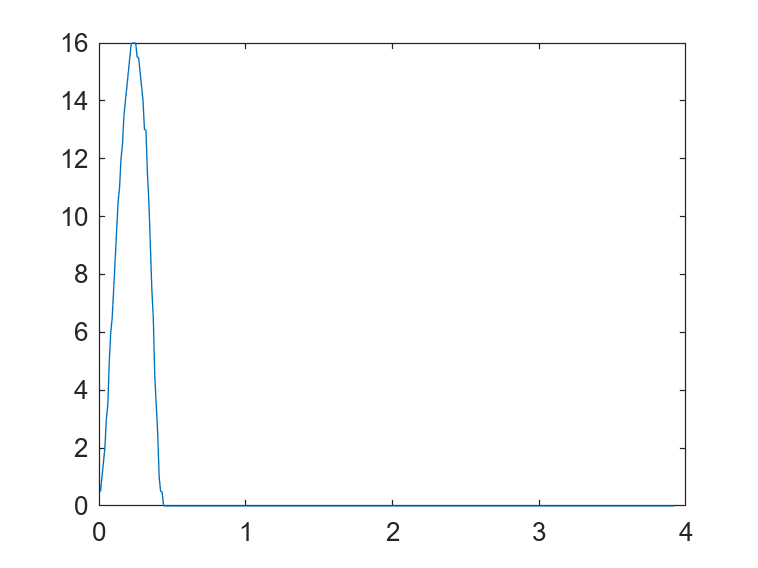

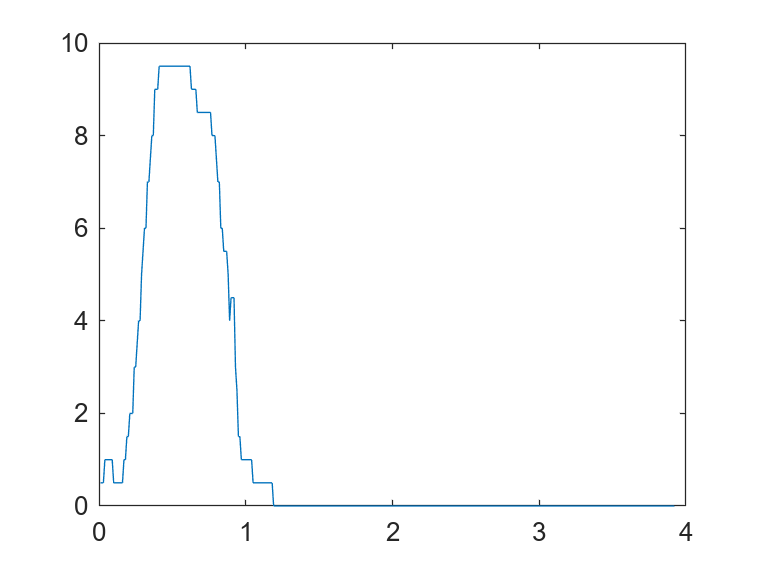


 for t=1:SizeOfForce(1,2)
     TimeForPlot1 = 0.01:0.01:TimeOfDuration;     
     ForceForPlot=ForceVector(:,t); 
     figure
     plot(TimeForPlot1,ForceForPlot)
     hold on
 end




 %FREQUENCY
FrequencyC1=0;
FrequencyC2=0;
FrequencyC3=0;
FrequencyPeakForce=0;
for s=1:SizeOfForce(1,2)
    if strcmp(x{5,s},'c1')
        FrequencyC1=FrequencyC1+1
    else if strcmp(x{5,s},'c2')
        FrequencyC2=FrequencyC2+1  
    else if strcmp(x{5,s},'c3')
        FrequencyC3=FrequencyC3+1  
    else if strcmp(x{5,s},'peakforce')
         FrequencyPeakForce=FrequencyPeakForce+1
    end
    end
    end
    end
end

FrequencyC2 = 1

FrequencyC3 = 1

FrequencyC2 = 2

FrequencyC3 = 2

FrequencyC3 = 3

FrequencyPeakForce = 1

FrequencyPeakForce = 2

FrequencyC2 = 3

FrequencyC3 = 4

FrequencyC3 = 5

FrequencyC3 = 6

FrequencyPeakForce = 3


FreqC1xMinute=FrequencyC1*60/TotalTimeOfVideo

FreqC1xMinute = 0

FreqC2xMinute=FrequencyC2*60/TotalTimeOfVideo

FreqC2xMinute = 6.3830

FreqC3xMinute=FrequencyC3*60/TotalTimeOfVideo

FreqC3xMinute = 12.7660

FreqPeakForcexMinute=FrequencyPeakForce*60/TotalTimeOfVideo

FreqPeakForcexMinute = 6.3830


%MEAN OF TIME OF EACH CATEGORY
TimeC1=0;
TimeC2=0;
TimeC3=0;
TimePeakForce=0;
for s=1:SizeOfForce(1,2)
    if strcmp(x{5,s},'c1')
        TimeC1=TimeC1+x{3,s}
    else if strcmp(x{5,s},'c2')
        TimeC2=TimeC2+x{3,s}
    else if strcmp(x{5,s},'c3')
        TimeC3=TimeC3+x{3,s}
    else if strcmp(x{5,s},'peakforce')
         TimePeakForce=TimePeakForce+x{3,s}
    end
    end
    end
    end
end

TimeC2 = 1.9600

TimeC3 = 2.5200

TimeC2 = 3.2200

TimeC3 = 4.6200

TimeC3 = 7.4800

TimePeakForce = 0.5300

TimePeakForce = 0.9600

TimeC2 = 4.4000

TimeC3 = 9.0700

TimeC3 = 10.2900

TimeC3 = 14.2100

TimePeakForce = 1.3700


TimeC1xMinute=TimeC1*60/TotalTimeOfVideo

TimeC1xMinute = 0

TimeC2xMinute=TimeC2*60/TotalTimeOfVideo   

TimeC2xMinute = 9.3617

TimeC3xMinute=TimeC3*60/TotalTimeOfVideo

TimeC3xMinute = 30.2340

TimePeakForcexMinute=TimePeakForce*60/TotalTimeOfVideo

TimePeakForcexMinute = 2.9149